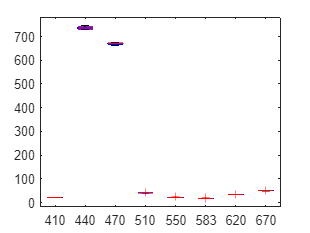

AS_wavelengths = [410, 440, 470, 510, 550, 583, 620, 670];
VEML_wavelengths = [650, 550, 450];

BLUE_Scaled = scale(BLUE);
[BLUE_10_AS, BLUE_10_VEML] = retrieve(BLUE_Scaled);
boxplot(transpose(BLUE_10_AS(1:8,:)),AS_wavelengths)

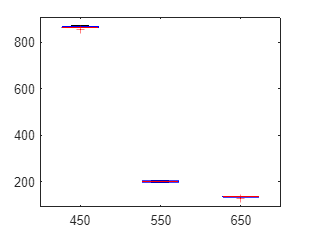

boxplot(transpose(BLUE_10_VEML(1:3,:)),VEML_wavelengths)

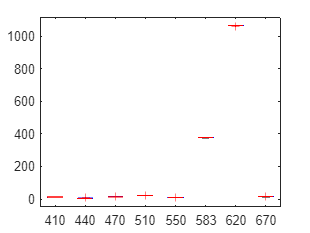


RED_Scaled = scale(RED);
[RED_10_AS, RED_10_VEML] = retrieve(RED_Scaled);
boxplot(transpose(RED_10_AS(1:8,:)),AS_wavelengths)

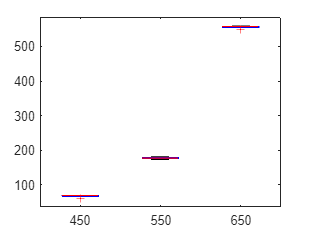

boxplot(transpose(RED_10_VEML(1:3,:)),VEML_wavelengths)

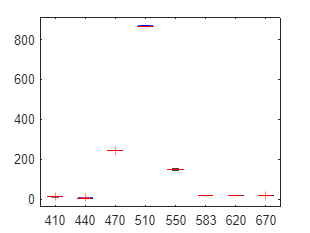


GREEN_Scaled = scale(GREEN);
[GREEN_10_AS, GREEN_10_VEML] = retrieve(GREEN_Scaled);
boxplot(transpose(GREEN_10_AS(1:8,:)),AS_wavelengths)

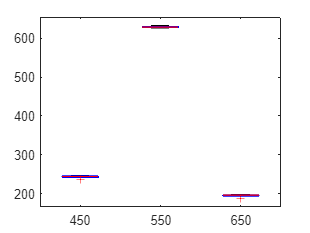

boxplot(transpose(GREEN_10_VEML(1:3,:)),VEML_wavelengths)

function COLOUR_Scaled = scale(COLOUR)
    factors = [4, 2, 1, 0.5, 0.25, 0.125];
    COLOUR_Scaled = cell(10,6);
    for j = 1:10
        for i = 1:6
            COLOUR_Scaled{j,i} = COLOUR{j, i}.*factors(i);
        end
    end
end

function [COLOUR_BRIGHTNESS_AS, COLOUR_BRIGHTNESS_VEML] = retrieve(COLOUR_Scaled)
    COLOUR_BRIGHTNESS_AS = zeros(9,6);
    COLOUR_BRIGHTNESS_VEML = zeros(4,6);
    for j = 1:9
        for i = 1:6
            COLOUR_BRIGHTNESS_AS(j,i) = COLOUR_Scaled{1,i}(1,j);
        end
    end
    for j = 1:4
        for i = 1:6
            COLOUR_BRIGHTNESS_VEML(j,i) = COLOUR_Scaled{1,i}(1,j+10);
        end
    end
end